# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\MSIT\RawData'];              % Raw Data Folder Directory

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

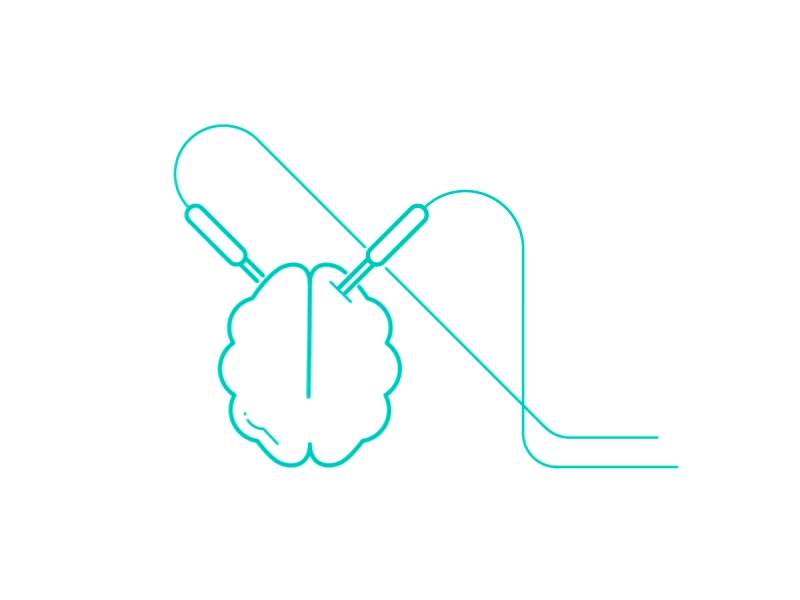

Deci.SubjectList        = 'gui';                                                  % Cell Array of strings, 'all' or 'gui'
Deci.Step               = 4;                                              % Which Step to implement 1-TD, 2-PP, 3-Art, 4-Analysis, 5-Plot
Deci.Proceed            = true;                                                                  % Continue to next step when current step is done?
Deci.PCom               = false;                                                                  % Activates Parallel Computing for PP and Analysis only
Deci.Folder.Version     = ['C:\Users\User\Desktop\MSIT\ProcessedData'];        % Output Folder Directory

## 1. Trial Definitions

Deci.DT.Type = 'Manual';                                                                        % Change if need alternative file, otherwise 'Manual' (expfunor2)
Deci.DT.Starts     = {5};                                                                       % Cell Array of Markers for Start codes.
Deci.DT.Ends       = {6};                                                                      % Cell Array of Markers for End codes.
Deci.DT.Markers    = {[12:19] [22:25] [37:39] [42:44]};                                   % Cell Array of Markers for Trial Defs
Deci.DT.Locks      = [10 20 30 69 40 50];                                                                % Num Array for each timelock (usually Stim, Rsp and Fdb Onset )
Deci.DT.Toi        = [-2 3];                                                                    % Time of Interest, be sure to include larger window for freq
Deci.DT.Block.Start   = {3};                                                                     % Cell Array of Markers for Block Starts
Deci.DT.Block.End     = {4};                                                                       % Cell Array of Markers for Block Starts
Deci.DT.Block.Markers = [];                                                                     % Num Array for each type of Block (if empty, Blocks are deliminated chronologically as -1,-2,..etc)

## 2. PreProcessing Steps

Deci.PP.HBP        = 1;                                                                         % Scalar,High-bandpass filter, in Hz.
Deci.PP.DownSample = [];                                                       % Downsample data
Deci.PP.More       = []                                                                         % Add additionall Preprocessing Parameters as according to ft_preprocessing

Deci = struct with fields:
         Folder: [1×1 struct]
    SubjectList: 'gui'
           Step: 1
        Proceed: 1
           PCom: 0
             DT: [1×1 struct]
             PP: [1×1 struct]


## 3. Artifact Rejection

Deci.Art.crittoilim = [-.5 1.5];                                                                % Critical Time Period for trial rejection (Respective to first Lock and Last Lock)
Deci.Art.muscle     = [];                                                                       % if empty, use default muscle parameters
Deci.Art.eog        = [];                                                                       % if empty, use default eog parameters
Deci.Art.RejectNans = true;
Deci.Art.PostICAbpf = [];                                                                       % Post ICA broadband pass filter, if desired

## 4. Analysis

#### General Set-Up

msit_singlecond;

#### Time-Frequency Analysis

Deci_Wavelet;

#### Cross-Frequency Coupling

% Currently Unavailable
Deci.Analysis.CFC.do = false;
Deci.Analysis.CFC.chanlow =  {'FCz'};
Deci.Analysis.CFC.chanhigh = {'CP3'};
Deci.Analysis.CFC.latencyhigh = [-.2 1];                                                        %no implementation yet to check for edge artifacts so be careful
Deci.Analysis.CFC.latencylow = [-.2 1];
Deci.Analysis.CFC.freqhigh = 'theta';
Deci.Analysis.CFC.freqlow = 'beta';
Deci.Analysis.CFC.timebin = 6;
Deci.Analysis.CFC.methods = {'mi' 'plv'};                                                       % can only currently handle '' or 'mi'(pac)

#### ERP

Deci.Analysis.ERP.do  = false;
Deci.Analysis.ERP.Toi = [-.5 1.5];

Extra

Deci.Analysis.Extra.QL.States = [20 21 23 24];
Deci.Analysis.Extra.QL.Actions = [31 32];
Deci.Analysis.Extra.QL.Reward  = [51 52];
Deci.Analysis.Extra.QL.Value  = {[20 10] [10 0] [0 -10] [-10 20]};

Deci.Analysis.Extra.do = false;
Deci.Analysis.Extra.list = [false];
Deci.Analysis.Extra.Functions = {'QL'};
Deci.Analysis.Extra.Params = {{Deci.Analysis.Extra.QL}};

## 5. Plotting

**General Set-Up**

Deci.Plot.Lock         = 'MSIT Stim Onset';                   % Which Lock to load                 
Deci.Plot.GrandAverage = true;                                   % Whether or not to grandaverage
Deci.Plot.FreqYScale   = 'linear';                   % Is the Frequency Y scale for Square plots on a linear or log scale?

% Comment your CondTitles here so you can refer to them for Math and Draw
msit_plot_singleconds;

#### Time-Frequency

Deci.Plot.Freq.Foi     = [4 8];                   % Frequency of Interest
Deci.Plot.Freq.Toi     = [-.5 1.5];                   % Time of Interest
Deci.Plot.Freq.Channel = {'FCz'};                   % Channel of Interest
Deci.Plot.Freq.Type    = 'TotalPower';                   % Use 'TotalPower','ITPC' or 'EvokedPower' (Currently Unavailable)
Deci.Plot.Freq.Bsl     = [-.5 -.2];                             % Baseline Correction Time
Deci.Plot.Freq.Topo    =true;
Deci.Plot.Freq.Square  =true;
Deci.Plot.Freq.Wire    =true;

**CFC**

%Currently Unavailable
Deci.Plot.CFC.Topo = true;
Deci.Plot.CFC.Square = true;
Deci.Plot.CFC.Hist = true;
Deci.Plot.CFC.Wire = true;
Deci.Plot.CFC.Roi = 'maxmin';          % Power Range of Interest

**ERP**

Deci.Plot.ERP.Toi = [0 .8];
Deci.Plot.ERP.Channel = {'FCz'};
Deci.Plot.ERP.Bsl = [-.5 -.2];           % Baseline Correction Time
Deci.Plot.ERP.Topo =false;
Deci.Plot.ERP.Wires =false;

#### Behavioral

Deci.Plot.Behv = [];
Deci.Plot.Behv.Source = 'Definition';

Deci.Plot.Behv.Acc.Total = {[1:16] [1:16]};
Deci.Plot.Behv.Acc.Subtotal = {[1:8] [9:16]};
Deci.Plot.Behv.Acc.Title = {'All Trials Percent' 'All Trials Percent'};
Deci.Plot.Behv.Acc.Subtitle = {'Opt Percent' 'Wst Percent'};

Deci.Plot.Behv.Acc.Block = [1:6];
Deci.Plot.Behv.Acc.Collapse.Trial =true;
Deci.Plot.Behv.Acc.Collapse.Block = true;
Deci.Plot.Behv.Acc.Collapse.Subject = true;
Deci.Plot.Behv.Acc.Collapse.Uneven = 'maxlength:nans';
Deci.Plot.Behv.Acc.Collapse.Movmean =  false;

Deci.Plot.Behv.RT.Draw = {[1:8] [9:16]};
Deci.Plot.Behv.RT.Title = {'All Trials RT' 'All Trials Percent'};
Deci.Plot.Behv.RT.Subtitle = {'Opt' 'Worst'};
Deci.Plot.Behv.RT.Locks = [1 2];

Deci.Plot.Behv.RT.Block = [1:6];
Deci.Plot.Behv.RT.Collapse.Trial =true;
Deci.Plot.Behv.RT.Collapse.Block = true;
Deci.Plot.Behv.RT.Collapse.Subject = true;
Deci.Plot.Behv.RT.Collapse.Uneven = 'maxlength:nans';

** Extra**

%Deci.Plot.Extra.List = true; plot or not 
%Deci.Plot.Extra.Functions = {}; whatever you're gonna use string
%formats/cells
%Deci.Plot.Extra.Params = {{}}; cells of cells corresponding to each
%function 

**Options**

Deci.Run.Behavior = false;
Deci.Run.Freq =true;
Deci.Run.ERP =false;
Deci.Run.CFC = false;
Deci.Run.Extra = false;

## ** 6. Run**

Deci_Backend(Deci);

----------------------
Starting DefineTrialor
Found 426 trials out of 508 for msitswm_054
Saving Preprocessing Data
Finished DefineTrial at 2.1815
----------------------
----------------------
Starting PreProcessor for msitswm_054
Implicit Rereference
Ocular Rereference
Highbandpass Filter
Saving Preprocessing Data
Finished PreProcessor at 151.0506
----------------------
----------------------
Starting Artifactor
searching for artifacts in 63 channels
searching in trial 508 from 508



detected 95 artifacts
the call to "ft_artifact_zvalue" took 158 seconds
searching for artifacts in 4 channels
searching in trial 508 from 508



detected 82 artifacts
the call to "ft_artifact_zvalue" took 19 seconds
detected  95 muscle artifacts
detected  82 eog artifacts
rejected   79 trials completely
rejected    0 trials partially
filled parts of    0 trials with nans
retained   23 trials with artifacts outside critical window
resulting 429 trials
the input is raw data with 63 channels and 508 trials


the call to "ft_redefinetrial" took 11 seconds
the call to "ft_rejectartifact" took 12 seconds
the input is raw data with 63 channels and 429 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 2 seconds
the input is raw data with 63 channels and 429 trials


showing a summary of the data for all channels and trials


computing metric [-|                                                       ]computing metric [----/                                                    ]computing metric [-------                                                  ]computing metric [---------\                                               ]computing metric [------------|                                            ]computing metric [---------------/                                         ]computing metric [------------------                                       ]computing metric [--------------------\                                    ]computing metric [-----------------------|                                 ]computing metric [--------------------------/                              ]computing metric [-------------------------------                          ]computing metric [---------------------------------\                       ]computing metric [------------------------------------|                    ]computing me

349 trials marked as GOOD, 80 trials marked as BAD
63 channels marked as GOOD, 0 channels marked as BAD
the following trials were removed: 54, 69, 70, 71, 72, 73, 90, 107, 108, 109, 110, 111, 112, 113, 114, 115, 116, 117, 118, 119, 120, 121, 122, 123, 124, 125, 126, 127, 128, 129, 130, 131, 132, 133, 134, 135, 136, 137, 138, 139, 140, 141, 142, 143, 144, 145, 146, 147, 148, 149, 150, 151, 152, 153, 154, 155, 156, 157, 158, 159, 160, 161, 162, 163, 164, 165, 166, 167, 168, 169, 176, 255, 270, 293, 305, 313, 361, 362, 385, 413
the call to "ft_rejectvisual" took 99 seconds
the input is raw data with 63 channels and 349 trials


baseline correcting data 
scaling data with 1 over 148.087261
concatenating data.............................................................................................................................................................................................................................................................................................................................................................
concatenated data matrix size 63x3303328
starting decomposition using runica

Input data size [20,3303328] = 20 channels, 3303328 frames/nAfter PCA dimension reduction,
  finding 20 ICA components using logistic ICA.
Decomposing 8258 frames per ICA weight ((400)^2 = 3303328 weights, Initial learning rate will be 0.001, block size 76.
Learning rate will be multiplied by 0.9 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-06 or after 512 steps.
Online bias adjustment will be used.
Removing

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds


the call to "ft_topoplotIC" took 7 seconds


reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the input is component data with 20 components and 63 original channels
the input is raw data with 20 channels and 508 trials
detected   0 visual artifacts


Error using matlab.internal.editor.FigureManager
Error while evaluating Figure SizeChangedFcn.



removing 4 components
keeping 16 components
not applying the backprojection matrix to the sensor description
the call to "ft_rejectcomponent" took 2 seconds


detected 97 artifacts
the call to "ft_artifact_zvalue" took 154 seconds


detected 69 artifacts
the call to "ft_artifact_zvalue" took 18 seconds
detected  97 muscle artifacts
detected  69 eog artifacts
rejected   66 trials completely
rejected    0 trials partially
filled parts of    0 trials with nans
retained   24 trials with artifacts outside critical window
resulting 442 trials
the input is raw data with 63 channels and 508 trials


the call to "ft_redefinetrial" took 12 seconds
the call to "ft_rejectartifact" took 12 seconds
the input is raw data with 63 channels and 442 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the input is raw data with 63 channels and 442 trials


showing a summary of the data for all channels and trials


computing metric [--|                                                      ]computing metric [-----/                                                   ]computing metric [---------                                                ]computing metric [----------\                                              ]computing metric [-------------|                                           ]computing metric [---------------/                                         ]computing metric [-------------------                                      ]computing metric [---------------------\                                   ]computing metric [------------------------|                                ]computing metric [--------------------------/                              ]computing metric [------------------------------                           ]computing metric [--------------------------------\                        ]computing metric [-----------------------------------|                     ]computing me

424 trials marked as GOOD, 18 trials marked as BAD
4 channels marked as GOOD, 59 channels marked as BAD
no channels were removed from the data
the following trials were removed: 63, 82, 174, 208, 237, 247, 258, 280, 282, 299, 300, 323, 338, 369, 390, 392, 394, 442


the call to "ft_rejectvisual" took 108 seconds


the input is raw data with 63 channels and 424 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 1 seconds
the input is raw data with 63 channels and 424 trials


showing a summary of the data for all channels and trials


computing metric [---|                                                     ]computing metric [-----/                                                   ]computing metric [---------                                                ]computing metric [-----------\                                             ]computing metric [--------------|                                          ]computing metric [----------------/                                        ]computing metric [--------------------                                     ]computing metric [---------------------\                                   ]computing metric [------------------------|                                ]computing metric [---------------------------/                             ]computing metric [------------------------------                           ]computing metric [--------------------------------\                        ]computing metric [-----------------------------------|                     ]computing me

408 trials marked as GOOD, 16 trials marked as BAD
63 channels marked as GOOD, 0 channels marked as BAD
the following trials were removed: 31, 32, 96, 123, 160, 213, 253, 269, 286, 290, 292, 304, 312, 325, 358, 366


the call to "ft_rejectvisual" took 98 seconds


the input is raw data with 63 channels and 408 trials


using electrodes specified in the configuration
computing SCD for trial 408 of 408



output surface laplacian is in uV/m^2
the call to "ft_scalpcurrentdensity" took 43 seconds
the input is raw data with 59 channels and 102 trials
resampling data
resampling data in trial 102 from 102

original sampling rate = 1000 Hz
new sampling rate = 500 Hz
the call to "ft_resampledata" took 7 seconds
the input is raw data with 59 channels and 102 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 59 channels and 102 trials


processing trials


trial 102, frequency 20 (39.98 Hz)

the call to "ft_freqanalysis" took 54 seconds


s:1 c:1 Lock1 time: 15.088
the input is raw data with 59 channels and 102 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 59 channels and 102 trials


processing trials
trial 102, frequency 20 (39.98 Hz)

the call to "ft_freqanalysis" took 54 seconds


s:1 c:1 Lock2 time: 14.532
the input is raw data with 59 channels and 102 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 59 channels and 102 trials


processing trials
trial 102, frequency 20 (39.98 Hz)

the call to "ft_freqanalysis" took 54 seconds


s:1 c:1 Lock3 time: 14.498
the input is raw data with 59 channels and 102 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 59 channels and 102 trials


processing trials
trial 102, frequency 20 (39.98 Hz)

the call to "ft_freqanalysis" took 53 seconds


s:1 c:1 Lock4 time: 14.576
the input is raw data with 59 channels and 102 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 59 channels and 102 trials


processing trials
trial 102, frequency 20 (39.98 Hz)

the call to "ft_freqanalysis" took 52 seconds


s:1 c:1 Lock5 time: 14.302
the input is raw data with 59 channels and 102 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds
the input is raw data with 59 channels and 102 trials


processing trials
trial 102, frequency 20 (39.98 Hz)

the call to "ft_freqanalysis" took 52 seconds
